% Calculo simbólico matlab

syms f1 f2 d M

clue = imread("c_clue.jpg");

% Unidades
nm = 1E-9;
um = 1E-6;
mm = 1E-3;

f1 = 20*mm;
f2 = 200*mm;
d = 1*mm;

% clueBW = rgb2gray(clue);
% new = imresize(clueBW,1024/600);
% new = double(new./255);
% imagesc(new)
% colormap gray

% Matriz de transferencia para la propagación de la distancia f1
propf1 = [1 f1; 0 1]

propf1 =     1.0000    0.0200
         0    1.0000


% Matriz de transferencia para el objetivo MO
objMO = [1 0; -1/f1 1]

objMO =      1     0
   -50     1


% Matriz de transferencia para la propagación de la distancia d
propd = [1 d; 0 1]

propd =     1.0000    0.0010
         0    1.0000


%Lente LT 
LT = [1 0; -1/f2 1]

LT =      1     0
    -5     1




% Matriz de transferencia para la propagación de la distancia f2
propf2 = [1 f2; 0 1]

propf2 =     1.0000    0.2000
         0    1.0000


Msys = propf1*objMO*propf1

Msys =          0    0.0200
  -50.0000         0


det(Msys)

ans = 1

L0 = (2*f1)

L0 = 0.0400

A = Msys(1,1)

A = 0

B = abs(Msys(1,2))

B = 0.0200

D = Msys(2,2)

D = 0


% Tamaño de la representación
Nx = 4096;
Ny = Nx;



% Longitud de Onda de iluminación
lambda = 533*nm;

% Limite de Resolución
LR = lambda*1000000*0.61/0.25

LR = 1.3005


% Condiciones de muestreo
dx = 6.513*mm/Nx; 
dy = dx;

%Limite de propagacion
zlim = Nx*dx^2/lambda

zlim = 0.0194

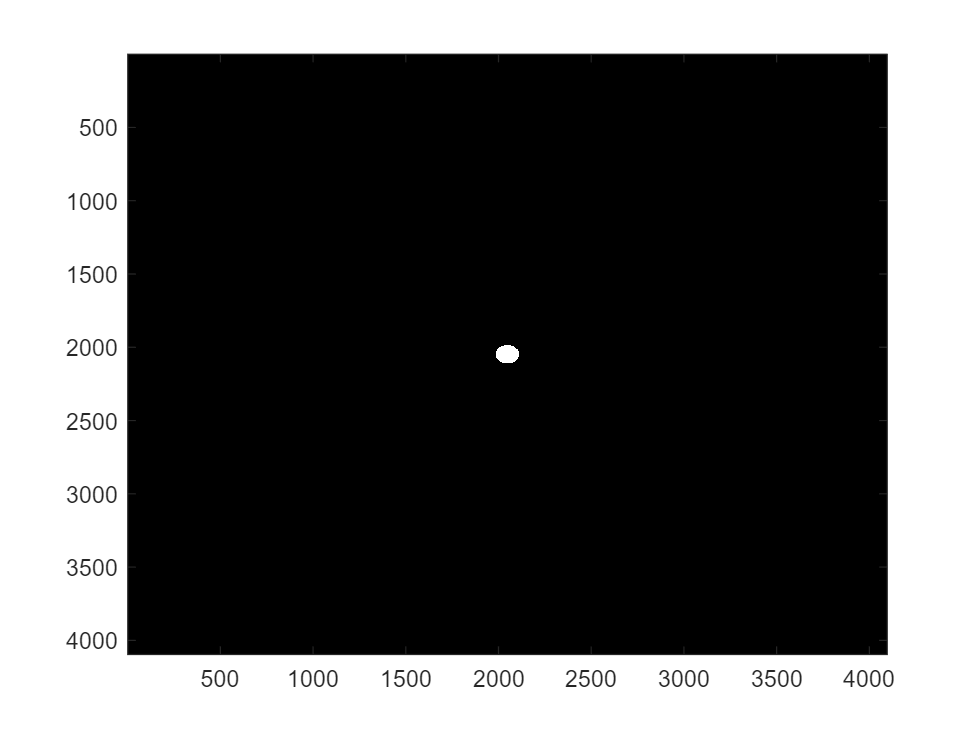


% Transmitancia
radioAberturaCirc = 100*um/dx; % Radio de 100um
aberturaCircular = filtroCircular ([Nx/2 Ny/2],radioAberturaCirc,[Ny Nx]);
radioObjeto = 45*um/dx; % Lado de 10um
objetoAnalisis = ~filtroCircular([Nx/2 Ny/2],radioObjeto,[Ny Nx]);

pantalla1 = (aberturaCircular);
imagesc(pantalla1);
colormap gray

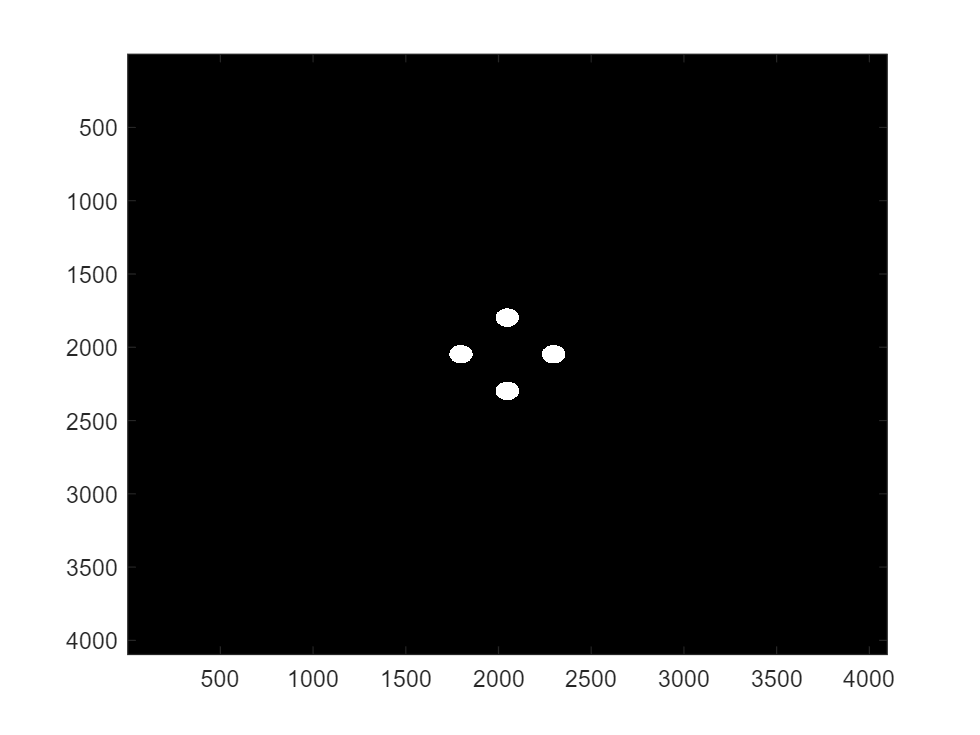


% Transmitancia
s = 250;
radioAberturaCirc2 = 100*um/dx; % Radio de 100um
aberturaCircular2 = filtroCircular ([(Nx/2)-s (Ny/2)],radioAberturaCirc2,[Ny Nx]);
aberturaCircular3 = filtroCircular ([(Nx/2)+s (Ny/2)],radioAberturaCirc2,[Ny Nx]);
aberturaCircular4 = filtroCircular ([(Nx/2) (Ny/2)-s],radioAberturaCirc2,[Ny Nx]);
aberturaCircular5 = filtroCircular ([(Nx/2) (Ny/2)+s],radioAberturaCirc2,[Ny Nx]);
pantalla2 = (aberturaCircular2+aberturaCircular3+aberturaCircular4+aberturaCircular5);
imagesc(pantalla2);

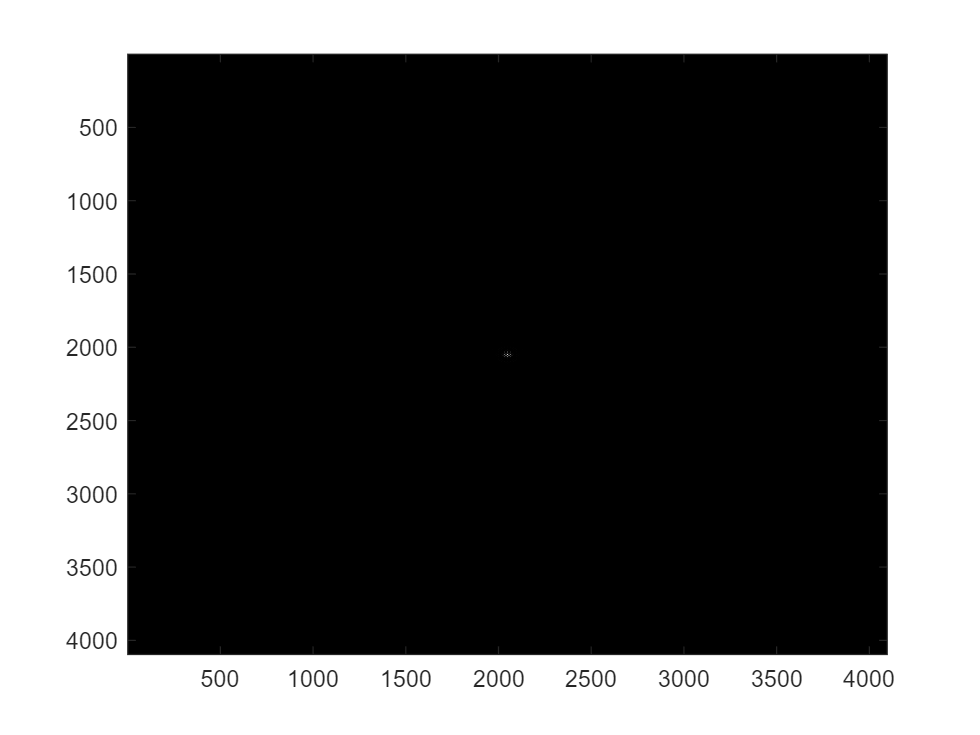

propagacionPantalla1 = transformadaFresnel(pantalla2,dx,dy,lambda,A,B,D,L0,"dft",false,"zoom",false);
intensidad1 = abs(propagacionPantalla1).^2;
imagesc(intensidad1)

%Transmitancia
radioPupila = 5*mm/dx; % Radio de 5 mm
Pupila = filtroCircular ([Nx/2 Ny/2],radioPupila,size(intensidad1));

Imagen2 = Pupila.*intensidad1;
imagesc(Imagen2)
colormap gray

L01 = d+f2;
Msys2 = propf2*LT*propd

Msys2 =          0    0.2000
   -5.0000    0.9950


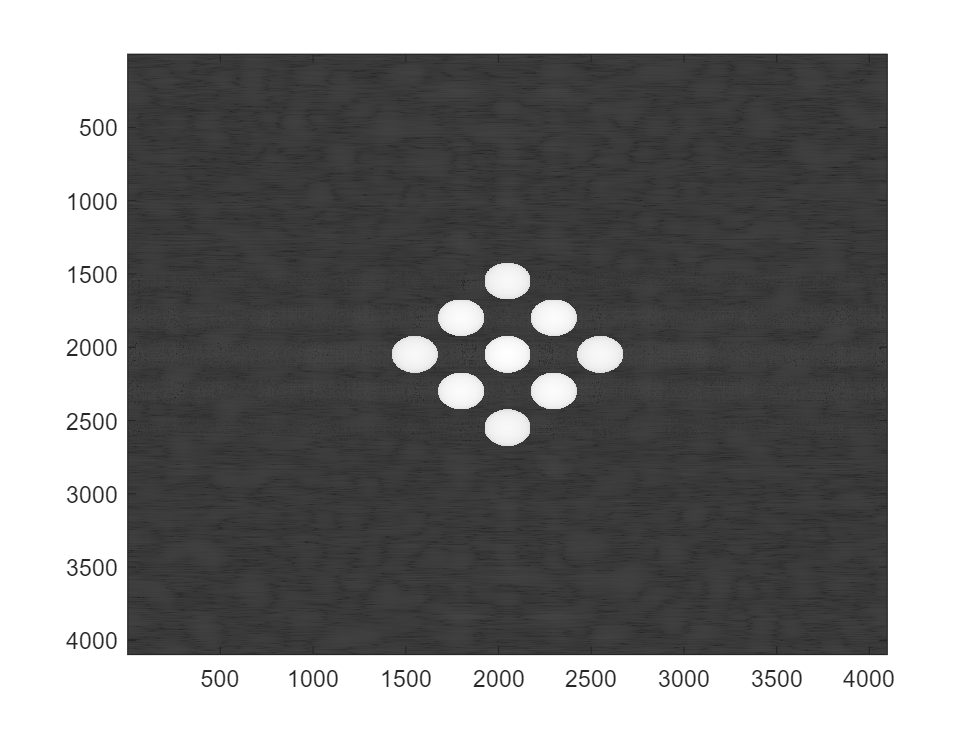

A2 = Msys2(1,1);
B2 = Msys2(1,2);
D2 = Msys2(2,2);

% Condiciones de muestreo
dx2 = dx;
dy2 = dx2;

propagacionImagen2 = transformadaFresnel(Imagen2,dx2,dy2,lambda,A2,B2,D2,L01,"dft",false,"zoom",false);
intensidad2 = abs(propagacionImagen2).^2;
imagesc(log(intensidad2))